### Signal generation:

clc
clear all

Fc = 60; %frequency 60Hz
Av =1;  % amplitude
Ts = 0.0005; % 1/0.0005 = 2 kHz  campionamento
StopTime = 0.1;             % seconds
t = (0:Ts:StopTime-Ts)';     % seconds
omega = 2*pi*Fc; % angular frequency constant over time

A =  [1 0; 0 1]; % valori paper: A = eye(2);
B = [0;0]; % valori paper: B = 0;
C =  [cos(omega*t), -sin(omega*t)];  % frequenza di 60Hz
D = 0;
W = eye(2);
U = 1;

Q = eye(2); %state noise covariance
R = 1;  % measurement noise covariance

x1 = 1*cos(0);     %x1 = Av*cos(phi);
x2 = 1*sin(0);     %x2 = Av*sin(phi);
x = zeros(length(t), 2);
x(1,:) = [x1, x2];


y_noise = 0.02 * randn(size(t));
x_noise = 0.0003 * randn(size(t));

y(1) = C(1,:)*x(1,:)' + y_noise(1);

for i=2:length(t)
    x(i,:) =  A*x(i-1,:)' + x_noise(i);
    y(i) = C(i,:)*x(i,:)' + y_noise(i);
end


### Kalman Filter output

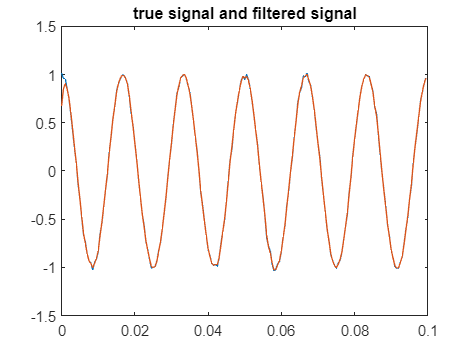

[y_hat, ~, ~, P_last, K_last, x_hat, K_steps, P_steps] = kalmanfilter(y, Q, R, 0.1);

e_real = x - x_hat;

figure();
plot(t, y, t, y_hat);
title('true signal and filtered signal');

Thm. 2 [Sinopoli]: given thath Cv belongs to Span(Gamma) , exists y* s.t. Gamma x y* = Cv. 

v is the unstable eigenvector for A

Gamma = diag( g1,..., gm) where m=number of sensors.  gi = 1 if belong to S_bad. We have only one sensor, so m =1.

lambda = 1; % autovalore di A
v = [0;1]; % autovettore di A

Gamma = diag([0,1]);

% Construction of ya_0 and ya_1

O = C(1:2, :);
[P,~,~] = dare(A',O',Q, R);
P

P =     1.4276    0.6241
    0.6241    7.9714


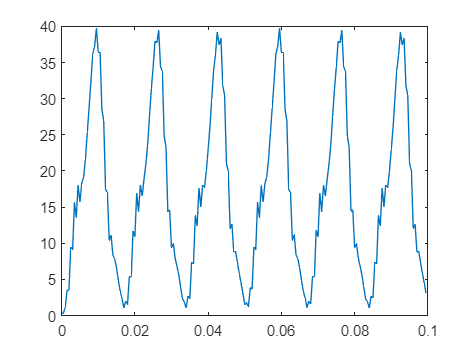

[S,~,L] = idare(A,B,W,U);
L = -L;
K = A*P*O'*inv(O*P*O'+R);

%cP = C*P*C' + R;
%invcP = inv(cP);

Co = -[(A-K*O*A)*K*Gamma K*Gamma];

ya = Co\v;
ya = reshape(ya,2,[]);

e(:,1) = -K*Gamma*ya(:,1);

z(:,1) = Gamma*ya(:,1);

e(:,2) = (A-K*O*A)*e(:,1)-K*Gamma*ya(:,2);
z(:,2) = O*A*e(:,1) + Gamma*ya(:,2);

M = max(norm(z(:,1)),norm(z(:,2)));

ya = ya/M;




for i = 3:length(t)
    ystar = C(i-1:i, :)*v;
    ya(:,i) = ya(:,i-2) - lambda^(i-2)/M*ystar;
end

for i=2:length(t)
     K = A*P*C(i-1:i, :)'*inv(C(i-1:i, :)*P*C(i-1:i, :)'+R);
     e(:,i) = (A-K*C(i-1:i, :)*A) * e(:,i-1) - K*Gamma * ya(:,i);
     z(:,i) = C(i-1:i, :)*A * e(:,i-1) + Gamma * ya(:,i);
end


K = A*P*O'*inv(O*P*O'+R);
hatx(:,1) = K*z(:,1);

for i = 2:length(t)
    K = A*P*C(i-1:i, :)'*inv(C(i-1:i, :)*P*C(i-1:i, :)'+R);
    hatx(:,i) = A*hatx(:,i-1)+K*z(:,i);
end

for i = 1:length(t)
    normz(i) = norm(z(:,i));
end

delta_x_prime = hatx + e;

delta_e = e' - e_real;


ya = Gamma*ya;
% ya = ya(2,:);

plot(t, normz)

### Functions:

function [filtered_sig, residue, cov_matrix, p0, K,  x_hat, K_toReturn, P1]= kalmanfilter(signal,Q_in,R_in,simulation_time)
    %this Kalman filter has been modified to follow an input siusoidal
    %"signal" with approximatley 60 Hz.
    %Q_in and R_in are tuning parameters.
    %simulation_time is the total simulation time(match input-signal).
    %filtered_sig is the Kalman-filtered output of the signal.
    time_vec=linspace(0,simulation_time,length(signal));
    A=[1.00 0.0;0.0 1.00];
    w=2*pi*60;
    %initilize values
    x0=[0;0];   %assume initial state = 0;
    p0=1*eye(size(A));
    Q=Q_in;
    R=R_in;
    K =0;
    
    z1 = zeros(size(signal));
    z2 = zeros(size(signal));
    residue = zeros(size(signal));
    cov_matrix = zeros(200, 2);
    for i=1:max(size(signal))
        % x_hat(k|k-1) = A x_hat(k-1)
        x_hat_pred = A*x0;

        C = [cos(w*time_vec(i)) -sin(w*time_vec(i))];
        
        %1 prediction error covariance P(k|k-1) = A P(k-1) A'+ Q
        pre_error_cov = A*p0*A'+Q;
        
        %2 kalman gain equation k(k) = P(k|k-1) C' (C P(k|k-1) C' + R)^-1
        K = A*pre_error_cov*C'*inv(C*pre_error_cov*C'+R);
        
        %3 filter equation x_hat(k) = x_hat(k|k-1) + k(k)( y(k) - C
        %x_hat(k|k-1) )
        x_hat = x_hat_pred + K*(signal(i)-C*x_hat_pred);
        
        %4 error covariance P(k) = (I - k(k) C) P(k|k-1)
        error_cov = pre_error_cov-K*C*pre_error_cov;
        
        z1(i)=x_hat(1);
        z2(i)=x_hat(2);

        %recreating the sinusoid   y_hat = C x_hat
        filtered_sig(i)=C*[z1(i);z2(i)];

        % residuo: r(t) = y(t)-y_hat(t|t-1)
        residue(i) = signal(i)-C*x_hat_pred;
        cov_matrix(i,1) = signal(i);
        cov_matrix(i,2) = C*x_hat_pred;
        x0=x_hat;
        p0=error_cov;   
        P1(:,:,i)=error_cov;   
        K_toReturn(:,i) = K;
        
    end
    x_hat = zeros(length(signal), 2);
    x_hat(:,1) = z1; 
    x_hat(:,2) = z2;
end

function [distance_vector] = euclidean_distance(amplitudes_signal, amplitudes_estimate, time)
    if (size(amplitudes_signal) ~= size(amplitudes_estimate))
        error('size of true signal and size of estimated signal are not equal');
    end
    distance_vector = zeros(size(amplitudes_signal));
    for t=1:length(distance_vector)
        p = [time(t) amplitudes_signal(t)];
        q = [time(t) amplitudes_estimate(t)];
        %distance_vector(t) = sqrt((amplitudes_signal(t) - amplitudes_estimate(t)^2));
        distance_vector(t) = sqrt((p(1) - q(1))^2 + (p(2) - q(2))^2); % formula della distanza tra due punti
        %distance_vector(t) = dtw(p, q, 'euclidean');
    end
end